# calculate the TR FI under the context of tumour monitoring

clc
clear

addpath(genpath('F:\OneDrive\UK_projects_local\project in UK 2024\MCX\mcx_git'))

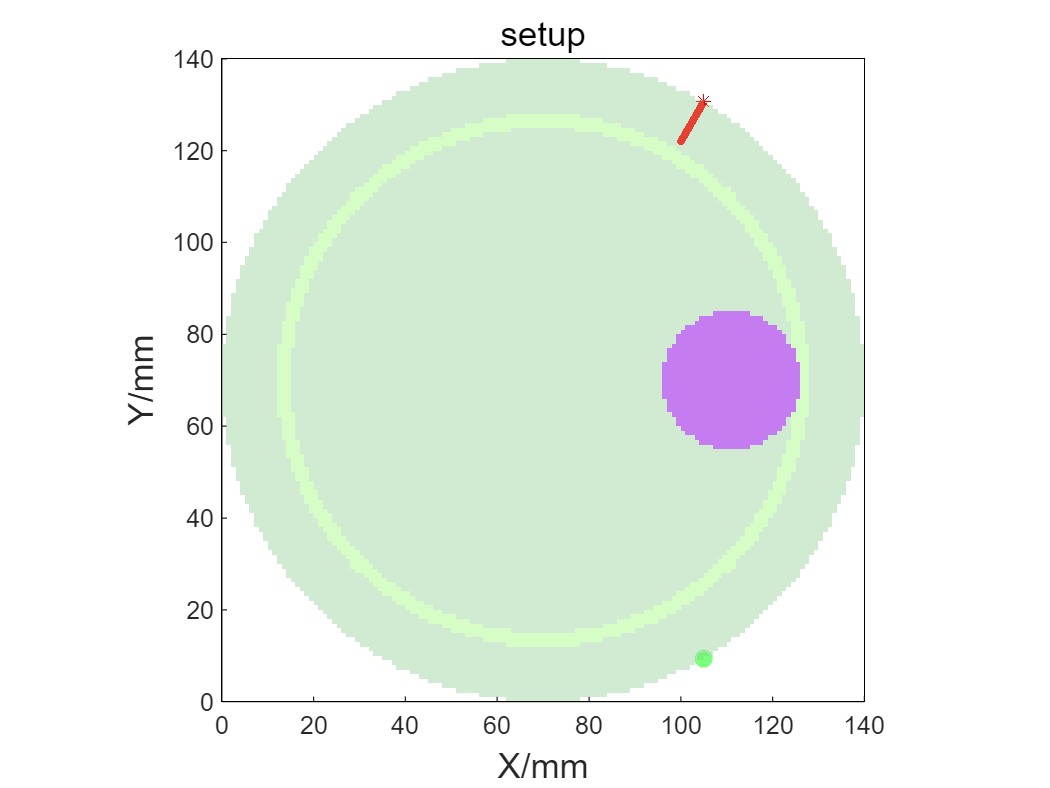

%% 2D CSF simulation main simulation
clear cfg_csf;

% % % % ------------general setting---------
cfg_csf.nphoton = 1e9;
cfg_csf.gpuid = '11'; % use two GPUs
cfg_csf.workload = [10,10];  % evenly use the two GPUs
cfg_csf.autopilot = 1;
cfg_csf.maxdetphoton = 1e8; % enough
brain_radius = 70;
cfg_csf.vol = permute(uint8(zeros([2*brain_radius,2*brain_radius])), [3, 1, 2]); % from 2d to 3d
cfg_csf.tstart = 0;
cfg_csf.tend = 3e-9;
cfg_csf.tstep = 5e-11;
cfg_csf.debuglevel = 'P'; % show progress bar
cfg_csf.unitinmm = 1;
cfg_csf.issrcfrom0 = 1;  % 1-first voxel is [0 0 0], [0]- first voxel is [1 1 1]
BinFlag = ((1:length(cfg_csf.tstart:cfg_csf.tstep:cfg_csf.tend)-1)'-1).*cfg_csf.tstep+cfg_csf.tstep/2; % the bin value of each timebin
source_angle = linspace(-pi/3,0,9)'; % angle range of source angle
det_angle = linspace(-pi/3,pi/3,17)'; % angle range of det angle
% source_angle = linspace(-pi/3,0,5)'; % angle range of source angle
% det_angle = linspace(-pi/3,pi/3,9)'; % angle range of det angle
SD_dist = abs(source_angle'-det_angle).*brain_radius; % get the distance between source and detector in mm
SD_dist = SD_dist(:);
simu_photon_numbers = round(10.^(8+(11-8)./max(SD_dist).*SD_dist));
% % % % -----------general setting end------------

% % % % build indices for the voxels, use voxel center
center_pos = [brain_radius brain_radius];
[grid_z,grid_y] = ndgrid(linspace(2*brain_radius-0.5,0.5,2*brain_radius),linspace(0.5,2*brain_radius-0.5,2*brain_radius));

dmua_tumour = 0.02; % difference in mua because of tumour

% % % % set brain segmentation
% % % % type [0 air, 1 GM, 2 CSF]
%---------the parameter is based on fang's paper-------------
cfg_csf.prop = [0 0 1 1;
    0.033 1 0 1.33;
    0.0420 0.01 0 1.33
    0.033+dmua_tumour 1 0 1.33];

D_from_center = sqrt((grid_z-center_pos(1)).^2+(grid_y-center_pos(2)).^2);
csf_radius = [58-3 58]; % typical CSF depth 12 mm, thickness 3 mm 

for i = 1:size(cfg_csf.vol,2)
    for j = 1:size(cfg_csf.vol,3)
        switch true
            case D_from_center(i,j)>=csf_radius(1)&&D_from_center(i,j)<csf_radius(2)
                cfg_csf.vol(1, i, j) = 2;
            case D_from_center(i,j)<=brain_radius
                cfg_csf.vol(1, i, j) = 1;
        end
    end
end

% % % % source set---------------------------------------
source_radius = brain_radius; source_angle_rad =  pi/3;
src_pos = [source_radius*cos(source_angle_rad),source_radius*sin(source_angle_rad)];
meas_radius = brain_radius; meas_angle_rad =  - pi/3; % pi/2 -0.5 pi/2+0.01
mea_pos = [meas_radius*cos(meas_angle_rad),meas_radius*sin(meas_angle_rad)];
cfg_csf.srcpos = [0, center_pos(1)+src_pos(1), center_pos(2)+src_pos(2)];
cfg_csf.srcdir = [0 -cos(source_angle_rad) -sin(source_angle_rad)];    % src dir must align in the plan (y-z in this case)
cfg_csf.srctype = 'pencil';
% % % %  source set end-----------------------------------

% % % % det set
cfg_csf.detpos = [0, center_pos(1)+mea_pos(1), center_pos(2)+mea_pos(2), 2];
% % % %  det set end

vol_background = cfg_csf.vol; % keep the background of the vol;
tumour_position = 41;

% % % % ----------set tumour-------------------
tuc_pos = [tumour_position 0];
tuC = [center_pos(1)-tuc_pos(1) center_pos(2)+tuc_pos(2)];
tuR = 15;
D2C = sqrt((grid_z-tuC(1)).^2+(grid_y-tuC(2)).^2);
for i = 1:size(cfg_csf.vol,2)
    for j = 1:size(cfg_csf.vol,3)
        if D2C(i,j)<=tuR
            cfg_csf.vol(1, i, j) = 3;
        end
    end
end
% ----------------------set tumour end-------------------

% set tumour mask
tumour_mask = squeeze(cfg_csf.vol);
tumour_mask(find(tumour_mask~=3))=0;
tumour_mask(find(tumour_mask==3))=1;
tumour_mask = rot90(tumour_mask); % so the tumour_mask here is already rotted
% figure;imagesc(tumour_mask);

% -------------------show the setup
figure,mcxpreview(cfg_csf); title('setup',FontSize=14); view([90,0]);
% figure,imagesc(double(squeeze(cfg_csf.vol)))
ylabel('X/mm',FontSize=14)
zlabel('Y/mm',FontSize=14)

## run the batch MCX simulation

cfg_csf.outputtype = 'flux';
rng('default') % reset random seed, make msimulation repeatable

%------------initial variables----------
weight = zeros(size(det_angle,1)*size(source_angle,1),1);
tpsfs = zeros(length(cfg_csf.tstart:cfg_csf.tstep:cfg_csf.tend)-1,size(det_angle,1)*size(source_angle,1));
jacobians = zeros(size(cfg_csf.vol,2),size(cfg_csf.vol,3), ...
    round((cfg_csf.tend - cfg_csf.tstart) / cfg_csf.tstep),size(det_angle,1)*size(source_angle,1));
dmua = 0.0001;

%-------------------iterate each depth
% tumour_pos = 10;
for tumour_pos = [20 25]

    %------------iter the tumour pos-----------------
    cfg_csf.vol = vol_background;
    tuc_pos = [tumour_pos 0];
    tuC = [center_pos(1)-tuc_pos(1) center_pos(2)+tuc_pos(2)];
    tuR = 15;
    D2C = sqrt((grid_z-tuC(1)).^2+(grid_y-tuC(2)).^2);
    for i = 1:size(cfg_csf.vol,2)
        for j = 1:size(cfg_csf.vol,3)
            if D2C(i,j)<=tuR
                cfg_csf.vol(1, i, j) = 3;
            end
        end
    end
    %------------iter the tumour pos-----------------

    h = waitbar(0, 'processing...');
    % i = size(det_angle,1); % longest distance
    for i = 52:size(det_angle,1)*size(source_angle,1)

        waitbar(i/(size(det_angle,1)*size(source_angle,1)),h,sprintf('finished %d%%', round(i/(size(det_angle,1)*size(source_angle,1))*100)));

        %------------update photon num------------
        cfg_csf.nphoton = simu_photon_numbers(i);
        % cfg_csf.nphoton = 1e10; % debug
        %------------update photon num------------

        %----------update src det positions---------
        [im,is] = ind2sub([size(det_angle,1),size(source_angle,1)],i);
        source_radius = brain_radius; source_angle_rad =  source_angle(is);
        meas_radius = brain_radius; meas_angle_rad = det_angle(im) ;
        src_pos = [source_radius*cos(source_angle_rad),source_radius*sin(source_angle_rad)];
        mea_pos = [meas_radius*cos(meas_angle_rad),meas_radius*sin(meas_angle_rad)];
        cfg_csf.srcpos = [0, center_pos(1)+src_pos(1), center_pos(2)+src_pos(2)];
        cfg_csf.detpos = [0, center_pos(1)+mea_pos(1), center_pos(2)+mea_pos(2), 2];
        cfg_csf.srcdir = [0 -cos(source_angle_rad) -sin(source_angle_rad)];    % src dir must align in the plan (y-z in this case)
        %----------update src det positions---------

        cfg_csf.seed = randi(1e6);
        evalc('[~, detpt_csf, ~, seeds] = mcxlab(cfg_csf);'); % no output information

        %----------get Jacobian-----------
        if ~isempty(detpt_csf.data)

            if size(detpt_csf.data,2)==cfg_csf.maxdetphoton
                error('maxdetphoton insufficent!')
            end

            weight(i) = sum(mcxdetweight(detpt_csf,cfg_csf.prop,cfg_csf.unitinmm));
            tpsfs(:,i) = mcxdettpsf(detpt_csf,1,cfg_csf.prop,[cfg_csf.tstart,cfg_csf.tend,cfg_csf.tstep])./cfg_csf.nphoton;
            % plot(tpsfs(:,i));
            newcfg = cfg_csf;
            newcfg.seed = seeds.data;
            newcfg.outputtype = 'jacobian';
            newcfg.detphotons = detpt_csf.data;
            evalc('[jaco] = mcxlab(newcfg);'); % no output information
            jacobians(:,:,:,i) = -rot90(squeeze(double(jaco.data)),1).* weight(i)./cfg_csf.nphoton;

        else
            error('no photon detected!');
        end
        %----------get Jacobian-----------


    end
    delete(h);
    save(sprintf('tpsfs_jacobians_dense_AngRang_pi_3_tumpos%d_CSF_250911_raw_data.mat',tumour_pos),"tpsfs","jacobians");
end


## #data analyse CSF

get rid of one variable by selecting the optimal S-D configuration for each moments and each tumour position

plot the best Fisher Information value and the corresponding S-D distance

also need to consider the time gates

% input tpsf and Jacobians should be the normalized tpsf
close all

%-----------data normalization------------
h = 6.626e-34; % Planck constant in Js
lambda = 800e-9; % wavelength in m
c = 299792453;
sp_eng = h.*c/(lambda); % single photon energy
% bandwidth = 1/exposure_time/2;
mpe = 3e-3; % w/mm^2
rep_rate = 300e6; % repetetion rate Hz 300M
single_pulse_energy = mpe./rep_rate; % J/mm^2
single_pulse_photon_count = single_pulse_energy./sp_eng;
exposure_time_tr = 1; % unit in second, the exposure time for the TCSPC
% BinFlag = (((1:length(cfg_csf.tstart:cfg_csf.tstep:cfg_csf.tend)-1)'-1).*cfg_csf.tstep+cfg_csf.tstep/2);
DCR = 100; % dark count rate 100/s
TCPSC_lim = 0.01*300e6;
% sensitive area is set to be 1mm^2
%-----------data normalization------------

tumour_pos_range = [20:5:40 45:5:54 54];

n = numel(tumour_pos_range);
metrics = {'m0','m1','m2','v','fullTPSF','earlyGate','lateGate'};


opt_FI_CSF = struct(); opt_D_CSF = struct();
for k = 1:numel(metrics)
    opt_FI_CSF.(metrics{k}) = zeros(n,1);
    opt_D_CSF.(metrics{k})  = zeros(n,1);
end

FI_CSF = struct(); D_CSF = struct();
for k = 1:numel(metrics)
    FI_CSF.(metrics{k}) = zeros(numel(SD_dist),1);
end



depth_index = 1;

% tumour_pos = 10; % debug

% % ------------figures for ploting--------------
% for k = 1:numel(metrics)
%     f(k) = figure('Name',metrics{k}, 'NumberTitle','off');
% end
% % ------------figures for ploting--------------

% tumour_pos = 50;  % debug
for tumour_pos = tumour_pos_range
    % % % % ----------update tumour mask -------------------
    tuct_pos1 = [tumour_pos 0];
    tuCt = [center_pos(1)-tuct_pos1(1) center_pos(2)+tuct_pos1(2)];
    tuR1 = 15;
    D2Cu = sqrt((grid_z-tuCt(1)).^2+(grid_y-tuCt(2)).^2);
    tumour_mask_it = zeros(2*brain_radius,2*brain_radius);
    for i = 1:size(tumour_mask_it,1)
        for j = 1:size(tumour_mask_it,2)
            if D2Cu(i,j)<=tuR1
                tumour_mask_it(i, j) = 1;
            end
        end
    end
    tumour_mask_it = rot90(tumour_mask_it);
    % figure;imagesc(tumour_mask_it);
    % imagesc(squeeze(log10(abs(sum(jacobians(:,:,:,1),3)))))
    % % % % ----------update tumour mask -------------------

    % data_load = load(sprintf("tpsfs_jacobians_AngRang_pi_3_tumpos%d.mat",tumour_pos));
    % data_load = load(sprintf("tpsfs_jacobians_tumpos%d.mat",tumour_pos));
    % data_load = load(sprintf("data3/tpsfs_jacobians_dense_AngRang_pi_3_tumpos%d.mat",tumour_pos));
    data_load = load(sprintf("data6/tpsfs_jacobians_dense_AngRang_pi_3_tumpos%d_CSF.mat",tumour_pos));

    %------------ normalize 3-----------make sure the highest count rate
    % matches the TCSPC standard
    % data_load.tpsfs = data_load.tpsfs./max(sum(data_load.tpsfs,1)).*TCPSC_lim;
    % data_load.jacobians =  data_load.jacobians./max(sum(data_load.tpsfs,1)).*TCPSC_lim;
    % tpsf_normalized = data_load.tpsfs./cfg_csf.nphoton.*single_pulse_photon_count.*rep_rate*exposure_time_tr;
    % Jacobians_norm = data_load.jacobians./cfg_csf.nphoton.*single_pulse_photon_count.*rep_rate*exposure_time_tr;


    %------------ normalize 1-----------make sure the highest count rate
    % % matches the TCSPC standard
    % data_load.tpsfs = data_load.tpsfs./max(sum(data_load.tpsfs,1)).*TCPSC_lim;
    % data_load.jacobians =  data_load.jacobians./max(sum(data_load.tpsfs,1)).*TCPSC_lim;
    %------------ normalize 1-----------make sure the highest count rate


    %--------------norm 2------------simple same norm
    tpsf_normalized_batch = data_load.tpsfs./cfg_csf.nphoton.*single_pulse_photon_count.*rep_rate*exposure_time_tr;
    Jacobians_norm_batch = data_load.jacobians./cfg_csf.nphoton.*single_pulse_photon_count.*rep_rate*exposure_time_tr;
    %--------------norm 2------------simple same norm

    % sd_ind = 111; % debug
    for sd_ind = 52:size(data_load.tpsfs,2) % starting from 52 to get rid of sampling noise

        % ----------- norm1-------------------
        % tpsf_sd =  data_load.tpsfs(:,sd_ind);
        % Jacobian_sd = squeeze(data_load.jacobians(:,:,:,sd_ind));
        % ----------- norm1-------------------

        % ------------ norm2-------------------
        tpsf_sd =  tpsf_normalized_batch(:,sd_ind);
        Jacobian_sd = squeeze(Jacobians_norm_batch(:,:,:,sd_ind));
        % ------------ norm2-------------------

        tpsf_normalized = tpsf_sd;
        Jacobians_norm = Jacobian_sd;
        % tpsf_normalized = tpsf_normalized+DCR*exposure_time_tr./length(tpsf_normalized); % plot(tpsf); hold on;
        J_Ni_mua = squeeze(sum(double(tumour_mask_it).*(Jacobians_norm),[1 2]));

        % %--------- normalize1--------------
        % if mpe/sp_eng*sum(tpsf_sd)>TCPSC_lim % this means input power should be lower
        %     tpsf_normalized = tpsf_sd.*TCPSC_lim./sum(tpsf_sd)*exposure_time_tr;
        %     Jacobians_norm =Jacobian_sd.*TCPSC_lim./sum(tpsf_sd).*exposure_time_tr;
        %     % flag(sd_ind) = 1;
        % 
        % else
        %     tpsf_normalized = tpsf_sd.*mpe/sp_eng.*exposure_time_tr;
        %     Jacobians_norm = Jacobian_sd.*mpe/sp_eng.*exposure_time_tr;
        %     % flag(sd_ind) = 0;
        %     % plot(tpsf_normalized)
        %     % sum(tpsf_normalized)
        %     % ratio = (mpe/sp_eng.*exposure_time_tr)./(TCPSC_lim./sum(tpsf_sd)*exposure_time_tr)
        % end
        % tpsf_normalized = tpsf_normalized+DCR*exposure_time_tr./length(tpsf_normalized); % plot(tpsf); hold on;

        % smoothing the tpsf when counts are small
        % if sum(tpsf_normalized)<1e6
        %     % tpsf = round(tpsf); % remove any PC <1
        %     tpsf_normalized = imgaussfilt(tpsf_normalized,1.5); % plot(tpsf_normalized), hold on% debug;
        % end
        % %--------- normalize1--------------

        %--------- normalize2--------------
        % tpsf_normalized = tpsf_sd.*single_pulse_photon_count.*rep_rate*exposure_time_tr;
        % Jacobians_norm = Jacobian_sd*single_pulse_photon_count.*rep_rate*exposure_time_tr;
        % tpsf_normalized = tpsf_normalized+DCR*exposure_time_tr./length(tpsf_normalized); % plot(tpsf); hold on;

        %--------- normalize2--------------


     
        % kernelSize = [1 1 5]; % [nx ny nt], must be odd integers
        % smoothedJ = imgaussfilt3(squeeze(Jacobians_norm(:,:,:,sd_ind)), 5, 'FilterSize', kernelSize);
        % imagesc(log10(abs(squeeze(sum(Jacobians_norm(:,:,:,sd_ind),3)))));  hold on
        % imagesc(tumour_mask_it)
        % %--------get rid of bad data--------
        % if tumour_pos == 15&&sd_ind==136
        %     smoothedJ(:,:,19) = 0;
        % end
        % if tumour_pos == 10&&sd_ind==145
        %     smoothedJ(:,:,41) = 0;
        % end
        % if tumour_pos == 15&&sd_ind==84
        %     smoothedJ(:,:,26) = 0;
        % end
        % if tumour_pos == 10&&sd_ind==50
        %     smoothedJ(:,:,31) = 0;
        % end
        % if tumour_pos == 10&&sd_ind==66
        %     smoothedJ(:,:,27) = 0;
        % end
        % %--------get rid of bad data--------

        % J_Ni_mua = squeeze(sum(double(tumour_mask_it).*(smoothedJ),[1 2]));  % plot(J_Ni_mua); hold on  % col vector how time bin change with mua
        % plot(J_Ni_mua); % debug

        % tumour_pos= 1,sd_ind=136 % debug
        

        % if tumour_pos == 15&&sd_ind==136
        %     J_Ni_mua(19) = 0;
        % end
        % if tumour_pos == 10&&sd_ind==145
        %     J_Ni_mua(41) = 0;
        % end
        % if tumour_pos == 15&&sd_ind==84
        %     J_Ni_mua(26) = 0;
        % end
        % if tumour_pos == 10&&sd_ind==50
        %     J_Ni_mua(31) = 0;
        % end
        % if tumour_pos == 10&&sd_ind==66
        %     J_Ni_mua(27) = 0;
        % end

        % -----------smooth the Jacobian----------------
        % if abs(sum(J_Ni_mua))<cfg_csf.nphoton.*single_pulse_photon_count.*rep_rate*exposure_time_tr*1e-17
        %     J_Ni_mua = imgaussfilt(J_Ni_mua,1.5);
        % end
        % plot(J_Ni_mua), hold on % debug

        %---------calculate the FI for moments-----------
        Em1 = sum(BinFlag.*tpsf_normalized,1)./sum(tpsf_normalized,1); % row vector
        Em2 = sum(BinFlag.^2.*tpsf_normalized,1)/sum(tpsf_normalized,1);
        Ev = Em2-Em1.^2;

        J_m0_Ni = ones(size(tpsf_normalized));
        J_m1_Ni = (BinFlag-Em1)./sum(tpsf_normalized,1); % col vector
        J_m2_Ni = (BinFlag.^2-Em2)./sum(tpsf_normalized,1);
        J_v_Ni = ((BinFlag-Em1).^2-Ev)./sum(tpsf_normalized,1);

        var_m1 = J_m1_Ni'*diag(tpsf_normalized)*J_m1_Ni;
        var_m2 = J_m2_Ni'*diag(tpsf_normalized)*J_m2_Ni;
        var_v = J_v_Ni'*diag(tpsf_normalized)*J_v_Ni;

        FI_CSF.(metrics{1})(sd_ind) = 1/sum(tpsf_normalized).*(J_m0_Ni'*J_Ni_mua).^2;
        FI_CSF.(metrics{2})(sd_ind) = 1/var_m1.*(J_m1_Ni'*J_Ni_mua).^2;
        FI_CSF.(metrics{3})(sd_ind) = 1/var_m2.*(J_m2_Ni'*J_Ni_mua).^2;
        FI_CSF.(metrics{4})(sd_ind) = 1/var_v.*(J_v_Ni'*J_Ni_mua).^2;

        %---------calculate the FI for full tpsf and time gates-----------
        one_over_tpsf = 1./tpsf_normalized';
        one_over_tpsf(isinf(one_over_tpsf)) = 0;
        FI_CSF.(metrics{5})(sd_ind) = one_over_tpsf*(J_Ni_mua).^2;
        FI_CSF.(metrics{6})(sd_ind) = 1/sum(tpsf_normalized(1:round(end/2))).*sum(J_Ni_mua(1:round(end/2))).^2;
        FI_CSF.(metrics{7})(sd_ind) =  1/sum(tpsf_normalized(round(end/2)+1:end)).*sum(J_Ni_mua(round(end/2)+1:end)).^2;
        %---------calculate the FI for full tpsf and time gates-----------

        %--------debug-----------
        % plot(J_Ni_mua(round(end/2)+1:end)),hold on
        % plot(J_Ni_mua(1:round(end/2))),hold on
        % J_Ni_mua = squeeze(sum(double(tumour_mask_it).*(Jacobians_norm(:,:,:,sd_ind)),[1 2])); plot(J_Ni_mua); hold on
        % if abs(sum(J_Ni_mua))<cfg_csf.nphoton.*single_pulse_photon_count.*rep_rate*exposure_time_tr*1e-17
        %     J_Ni_mua = imgaussfilt(J_Ni_mua,1.5); plot(J_Ni_mua); hold on
        % end
        % figure;plot(tpsf(round(end/2)+1:end))

    end

    % % ----debug plot all the metrics in a fixed depth
    % figure;
    % % for ii = 1:numel(metrics)
    % for ii = 1
    %     plot(log10(FI.(metrics{ii}))); hold on
    % end
    % legend(metrics)
    % grid on
    % 
    % m01 = FI.m0;
    % m02 = FI.m0;
    % figure; plot(log10(m01)), hold on;
    % plot(log10(m02))
    %----debug plot all the metrics in a fixed depth

    % get rid of inf------------
    for ii = 1:numel(metrics)
        FI_CSF.(metrics{ii})(isinf(FI_CSF.(metrics{ii}))) = 0;
    end

    % selete optimal value and distance-------------
    for ii = 1:numel(metrics)
        [v,i] = max(FI_CSF.(metrics{ii}));
        opt_FI_CSF.(metrics{ii})(depth_index) = v;
        opt_D_CSF.(metrics{ii})(depth_index) = SD_dist(i);
    end


    % for ii = 1:numel(metrics)
    %     figure(f(ii));   % use the handle
    %     plot(log10(FI.(metrics{ii}))); hold on
    %     title(metrics{ii})
    % end

    depth_index = depth_index + 1;


end


## plot the result figure of the optimize Fisher Value

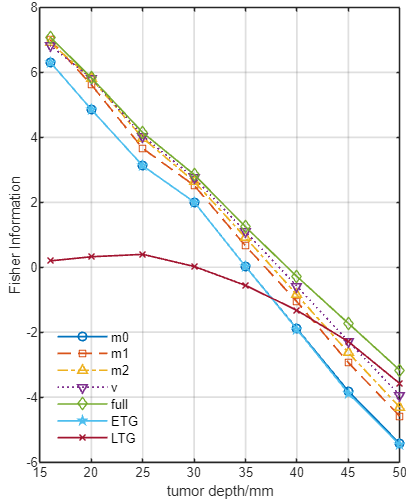

close all;

% -----------Desired sizes (cm)
figW = 17.2/2;   % figure width
figH = 17.2*0.618;    % figure height
axW  = figW-3.5*0.282;    % axes width
axH  = figH-3.5*0.282;    % axes height
axLeft = 3*0.282;  % left margin (from figure left edge)
axBottom = 3*0.282; % bottom margin

% -------- Create the figure at the given size
fig1 = figure;
ax1 = axes('Parent',fig1);

set(fig1, ...
    'Units',      'centimeters', ...
    'Position',   [2 2 figW figH], ...     % [left bottom width height]
    'PaperUnits', 'centimeters', ...
    'PaperPosition',[0 0 figW figH], ...
    'PaperSize',  [figW figH]);
set(ax1, ...
    'Units',      'centimeters', ...
    'Position',   [axLeft axBottom axW axH]);  % [left bottom width height] within fig

%-- Prepare data series and styles -----------------------------------------
x = brain_radius - tumour_pos_range;

lineSpecs = {'-','--','-.',':','-','-','-'};   % line styles
markers = {'o', 's', '^', 'v', 'd', 'p', 'x'};
% you can customize markers too, e.g. '-o','--s', etc.
% lineSpecs = {'-o','--s','-.^',':v','-d','-p','-x'};

labels = {'m0','m1','m2','v','full','ETG','LTG'};

%-- Plot loop ---------------------------------------------------------------
hold on
for k = 1:numel(metrics)
    plot(ax1, x, log10(opt_FI_CSF.(metrics{k})), lineSpecs{k}, 'LineWidth', 1, 'Marker',markers{k},'MarkerSize',5);
end
hold off

%-- Beautify ----------------------------------------------------------------
% xlim(ax1,[13.7 53.7])
% ylim(ax1,[-6.66 -2.02])
xlabel('tumor depth/mm');
ylabel('Fisher Information');
grid on; box(ax1,'on');
ax = gca;
ax.LineWidth = 1;
ax.FontSize = 8;
ax.FontName = 'Arial';

legend(labels, 'Location','southwest', 'Box','off', ...
    'FontSize',8, 'FontName','arial');

% print(fig1, 'F4.png', '-dpng', '-r1200');


%---------generate sub fig with fixed axis
% 1) 

% -----------Desired sizes (cm)
figW_sub = 16.8/2;   % figure width
figH_sub = 16.8*0.618/2;    % figure height
axW  = 0.9*figW_sub;   % axes width
axH  = figH_sub*0.9;    % axes height
axLeft = (figW_sub-axW)./1.5;  % left margin (from figure left edge)
axBottom = (figH_sub-axH)./1.5; % bottom margin

x_limits = [15.5 22];
y_limits = [ -8.75 -7];
fig11 = figure;
set(fig11, ...
    'Units','centimeters',  'Position',[2 2 figW_sub figH_sub], ...
    'PaperUnits','centimeters','PaperPosition',[0 0 figW_sub figH_sub], ...
    'PaperSize',[figW_sub figH_sub]);

% 2) 复制坐标区
ax11 = copyobj(ax1, fig11);

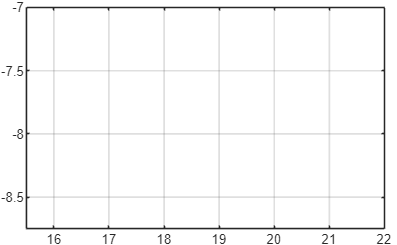

set(ax11, 'Units','centimeters', ...
         'Position',[axLeft axBottom axW axH]);

% 3) 设置放大范围
xlim(ax11, x_limits);
ylim(ax11, y_limits);
xlabel('')   % deletes the X‑label
ylabel('')   % deletes the Y‑label
title('')    % deletes the title (if needed)

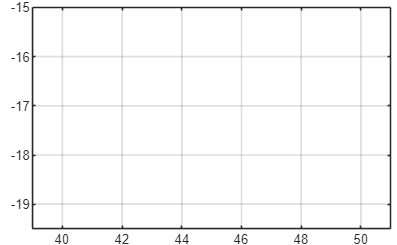

drawnow;  % draw zoom figure
% 4) 导出
% print(fig11,'F2S1_zoom.png','-dpng','-r1200');



%---------generate sub fig with fixed axis
% 2 

% -----------Desired sizes (cm)
figW_sub = 16.8/2;   % figure width
figH_sub = 16.8*0.618/2;    % figure height
axW  = 0.9*figW_sub;   % axes width
axH  = figH_sub*0.9;    % axes height
axLeft = (figW_sub-axW)./1.2;  % left margin (from figure left edge)
axBottom = (figH_sub-axH)./1.5; % bottom margin

x_limits = [39 51];
y_limits = [ -19.5 -15];
fig12 = figure;
set(fig12, ...
    'Units','centimeters',  'Position',[2 2 figW_sub figH_sub], ...
    'PaperUnits','centimeters','PaperPosition',[0 0 figW_sub figH_sub], ...
    'PaperSize',[figW_sub figH_sub]);

% 2) 复制坐标区
ax12 = copyobj(ax1, fig12);
set(ax12, 'Units','centimeters', ...
         'Position',[axLeft axBottom axW axH]);

% 3) 设置放大范围
xlim(ax12, x_limits);
ylim(ax12, y_limits);
xlabel('')   % deletes the X‑label
ylabel('')   % deletes the Y‑label
title('')    % deletes the title (if needed)


% print(fig12,'F2S2_zoom.png','-dpng','-r1200');


## data analysis, ploting the best S-D distance

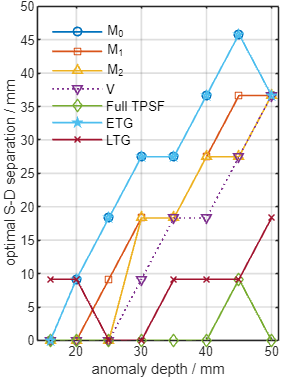

close all;

% -----------Desired sizes (cm)
figW = 6;   % figure width
figH = 8;    % figure height
axLeft = 0.8;  % left margin (from figure left edge)
axBottom = 0.8; % bottom margin
axW = figW-axLeft-0.1;    % axes width
axH = figH-axBottom-0.15;   % axes height

% -----------------Create the figure at the given size
fig2 = figure;
ax2 = axes('Parent',fig2);

set(fig2, ...
    'Units',      'centimeters', ...
    'Position',   [2 2 figW figH], ...     % [left bottom width height]
    'PaperUnits', 'centimeters', ...
    'PaperPosition',[0 0 figW figH], ...
    'PaperSize',  [figW figH]);
set(ax2, ...
    'Units',      'centimeters', ...
    'Position',   [axLeft axBottom axW axH]);  % [left bottom width height] within fig

x = brain_radius - tumour_pos_range;

% Define one style spec per curve: [LineStyle, Marker]
% You can mix-and-match '-' '--' '-.' ':'  with markers 'o', 's', '^', etc.
lineSpecs = {'-','--','-.',':','-','-','-'};   % line styles
markers = {'o', 's', '^', 'v', 'd', 'p', 'x'};

% % (Optional) a matching color spec (as RGB triplets) if you want to override the default cycle
% colors = [0    0.4470 0.7410;   % MATLAB default blue
%           0.8500 0.3250 0.0980; % red
%           0.9290 0.6940 0.1250; % yellow
%           0.4940 0.1840 0.5560; % purple
%           0.4660 0.6740 0.1880; % green
%           0.3010 0.7450 0.9330; % cyan
%           0.6350 0.0780 0.1840];% maroon

labels = {'M_0','M_1','M_2','V','Full TPSF','ETG','LTG'};

hold on
for k = 1:numel(metrics)
    plot(ax2, x,opt_D_CSF.(metrics{k}), ...
        'LineStyle' , lineSpecs{k}(1), ...
        'LineWidth' , 1, ...
        'Marker'    , markers{k}, ...
        MarkerSize=5);
end
hold off
box(ax2,'on'); grid on;
xlabel('anomaly depth / mm');
ylabel('optimal S-D separation / mm')
xlim(ax2,[14 51])
ylim(ax2,[0 50]);

ax = gca;                       % current axes
ax.LineWidth   = 1;             % axes box thickness
ax.FontName    = 'Arial';
ax.FontSize    = 8;            % journal‐style font size
ax.TickDir     = 'in';         % ticks outside
legend(labels, 'Location','northwest', 'Box','off', ...
    'FontSize',8, 'FontName','arial');
print(fig2, 'F3_1_140825.png', '-dpng', '-r1200');

## analyse the Jacobian Matrix

we should get rid of those measurements that are suffing from random sampling noise.

This means that CSF will lead more photons inside the 

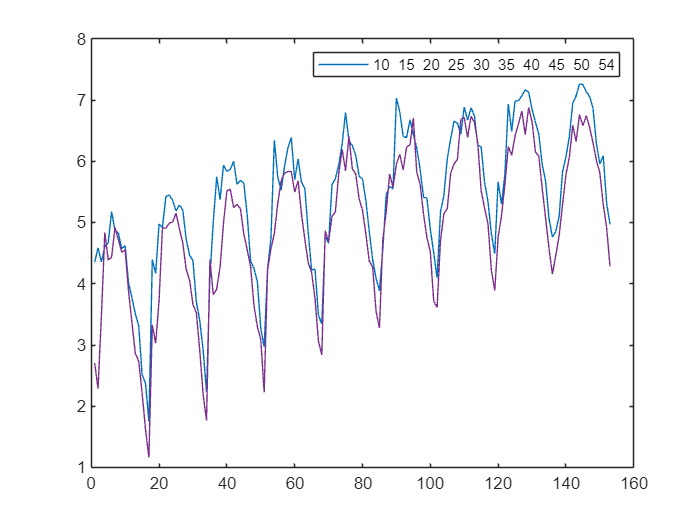

tumour_pos_range = [10:5:54 54];
sum_j = zeros(length(tumour_pos_range),length(SD_dist));
pos_ind = 1;
% for tumour_pos = tumour_pos_range
for tumour_pos = 20

    % % % % ----------update tumour mask -------------------
    tuct_pos1 = [tumour_pos 0];
    tuCt = [center_pos(1)-tuct_pos1(1) center_pos(2)+tuct_pos1(2)];
    tuR1 = 15;
    D2Cu = sqrt((grid_z-tuCt(1)).^2+(grid_y-tuCt(2)).^2);
    tumour_mask_it = zeros(2*brain_radius,2*brain_radius);
    for i = 1:size(tumour_mask_it,1)
        for j = 1:size(tumour_mask_it,2)
            if D2Cu(i,j)<=tuR1
                tumour_mask_it(i, j) = 1;
            end
        end
    end
    tumour_mask_it = rot90(tumour_mask_it);

    % data_load = load(sprintf("data6/tpsfs_jacobians_dense_AngRang_pi_3_tumpos%d_CSF.mat",tumour_pos));
    data_load = load(sprintf("data5/tpsfs_jacobians_dense_AngRang_pi_3_tumpos%d.mat",tumour_pos));

    tpsf_normalized = data_load.tpsfs.*single_pulse_photon_count.*rep_rate*exposure_time_tr;
    Jacobians_norm = data_load.jacobians.*single_pulse_photon_count.*rep_rate*exposure_time_tr;
    for k = 1:size(tpsf_normalized,2)
        sum_j(pos_ind,k) = sum(tumour_mask_it.*Jacobians_norm(:,:,:,k),'all');
    end

    pos_ind = pos_ind+1;
end

% figure; 
for i = 1:size(sum_j,1)
plot(log10(abs(sum_j(i,:)))); hold on
end
legend(num2str(tumour_pos_range))

## show the S-D position

cfg_sd_plot = cfg_csf;
ind_plot_sd = 126;

[im,is] = ind2sub([size(det_angle,1),size(source_angle,1)],ind_plot_sd);

source_radius = brain_radius; source_angle_rad =  source_angle(is);
meas_radius = brain_radius; meas_angle_rad = det_angle(im) ;

src_pos = [source_radius*cos(source_angle_rad),source_radius*sin(source_angle_rad)];
mea_pos = [meas_radius*cos(meas_angle_rad),meas_radius*sin(meas_angle_rad)];
cfg_sd_plot.srcpos = [0, center_pos(1)+src_pos(1), center_pos(2)+src_pos(2)];
cfg_sd_plot.detpos = [0, center_pos(1)+mea_pos(1), center_pos(2)+mea_pos(2), 2];
cfg_sd_plot.srcdir = [0 -cos(source_angle_rad) -sin(source_angle_rad)];    % src dir must align in the plan (y-z in this case)

figure,mcxpreview(cfg_sd_plot); view([90,0]);

## CSF analyse

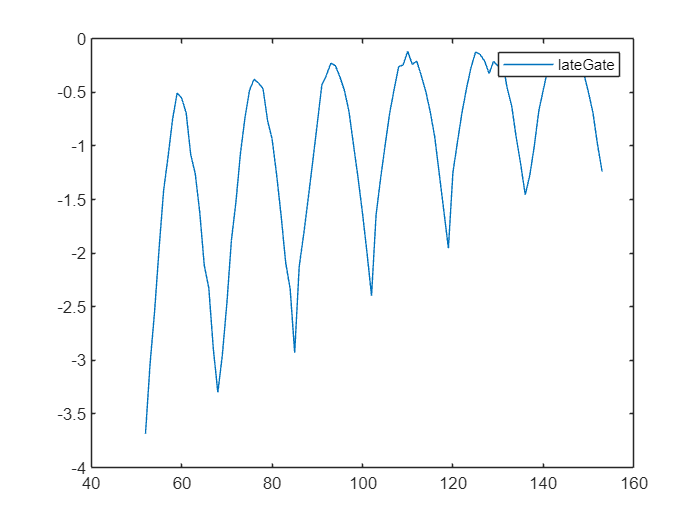

% input tpsf and Jacobians should be the normalized tpsf
close all

%-----------data normalization------------
h = 6.626e-34; % Planck constant in Js
lambda = 800e-9; % wavelength in m
c = 299792453;
sp_eng = h.*c/(lambda); % single photon energy
% bandwidth = 1/exposure_time/2;
mpe = 3e-3; % w/mm^2
rep_rate = 300e6; % repetetion rate Hz 300M
single_pulse_energy = mpe./rep_rate; % J/mm^2
single_pulse_photon_count = single_pulse_energy./sp_eng;
exposure_time_tr = 1; % unit in second, the exposure time for the TCSPC
% BinFlag = (((1:length(cfg_csf.tstart:cfg_csf.tstep:cfg_csf.tend)-1)'-1).*cfg_csf.tstep+cfg_csf.tstep/2);
DCR = 100; % dark count rate 100/s
TCPSC_lim = 0.01*300e6;
% sensitive area is set to be 1mm^2
%-----------data normalization------------

tumour_pos_range = [20:5:54 54];

n = numel(tumour_pos_range);
metrics = {'m0','m1','m2','v','fullTPSF','earlyGate','lateGate'};

opt_FI = struct(); opt_D = struct();
for k = 1:numel(metrics)
    opt_FI.(metrics{k}) = zeros(n,1);
    opt_D.(metrics{k})  = zeros(n,1);
end

FI = struct(); D = struct();
for k = 1:numel(metrics)
    FI.(metrics{k}) = zeros(numel(SD_dist),1);
end

depth_index = 1;


for tumour_pos = 50
    % % % % ----------update tumour mask -------------------
    tuct_pos1 = [tumour_pos 0];
    tuCt = [center_pos(1)-tuct_pos1(1) center_pos(2)+tuct_pos1(2)];
    tuR1 = 15;
    D2Cu = sqrt((grid_z-tuCt(1)).^2+(grid_y-tuCt(2)).^2);
    tumour_mask_it = zeros(2*brain_radius,2*brain_radius);
    for i = 1:size(tumour_mask_it,1)
        for j = 1:size(tumour_mask_it,2)
            if D2Cu(i,j)<=tuR1
                tumour_mask_it(i, j) = 1;
            end
        end
    end
    tumour_mask_it = rot90(tumour_mask_it);
    % figure;imagesc(tumour_mask_it);
    % imagesc(squeeze(log10(abs(sum(jacobians(:,:,:,1),3)))))
    % % % % ----------update tumour mask -------------------

    % data_load = load(sprintf("tpsfs_jacobians_AngRang_pi_3_tumpos%d.mat",tumour_pos));
    % data_load = load(sprintf("tpsfs_jacobians_tumpos%d.mat",tumour_pos));
    % data_load = load(sprintf("data3/tpsfs_jacobians_dense_AngRang_pi_3_tumpos%d.mat",tumour_pos));
    data_load_csf = load(sprintf("data6/tpsfs_jacobians_dense_AngRang_pi_3_tumpos%d_CSF.mat",tumour_pos));

 
    %------------ normalize 1-----------make sure the highest count rate
    % % matches the TCSPC standard
    % data_load.tpsfs = data_load.tpsfs./max(sum(data_load.tpsfs,1)).*TCPSC_lim;
    % data_load.jacobians =  data_load.jacobians./max(sum(data_load.tpsfs,1)).*TCPSC_lim;
    %------------ normalize 1-----------make sure the highest count rate


    %--------------norm 2------------simple same norm
    tpsf_normalized_batch = data_load.tpsfs./cfg_csf.nphoton.*single_pulse_photon_count.*rep_rate*exposure_time_tr;
    Jacobians_norm_batch = data_load.jacobians./cfg_csf.nphoton.*single_pulse_photon_count.*rep_rate*exposure_time_tr;
    %--------------norm 2------------simple same norm

    % sd_ind = 111; % debug
    for sd_ind = 52:size(data_load.tpsfs,2) % starting from 52 to get rid of sampling noise

        % ----------- norm1-------------------
        % tpsf_sd =  data_load.tpsfs(:,sd_ind);
        % Jacobian_sd = squeeze(data_load.jacobians(:,:,:,sd_ind));
        % ----------- norm1-------------------

        % ------------ norm2-------------------
        tpsf_sd =  tpsf_normalized_batch(:,sd_ind);
        Jacobian_sd = squeeze(Jacobians_norm_batch(:,:,:,sd_ind));
        % ------------ norm2-------------------

        tpsf_normalized = tpsf_sd;
        Jacobians_norm = Jacobian_sd;
        % tpsf_normalized = tpsf_normalized+DCR*exposure_time_tr./length(tpsf_normalized); % plot(tpsf); hold on;
        J_Ni_mua = squeeze(sum(double(tumour_mask_it).*(Jacobians_norm),[1 2]));
  
        %---------calculate the FI for moments-----------
        Em1 = sum(BinFlag.*tpsf_normalized,1)./sum(tpsf_normalized,1); % row vector
        Em2 = sum(BinFlag.^2.*tpsf_normalized,1)/sum(tpsf_normalized,1);
        Ev = Em2-Em1.^2;

        J_m0_Ni = ones(size(tpsf_normalized));
        J_m1_Ni = (BinFlag-Em1)./sum(tpsf_normalized,1); % col vector
        J_m2_Ni = (BinFlag.^2-Em2)./sum(tpsf_normalized,1);
        J_v_Ni = ((BinFlag-Em1).^2-Ev)./sum(tpsf_normalized,1);

        var_m1 = J_m1_Ni'*diag(tpsf_normalized)*J_m1_Ni;
        var_m2 = J_m2_Ni'*diag(tpsf_normalized)*J_m2_Ni;
        var_v = J_v_Ni'*diag(tpsf_normalized)*J_v_Ni;

        FI.(metrics{1})(sd_ind) = 1/sum(tpsf_normalized).*(J_m0_Ni'*J_Ni_mua).^2;
        FI.(metrics{2})(sd_ind) = 1/var_m1.*(J_m1_Ni'*J_Ni_mua).^2;
        FI.(metrics{3})(sd_ind) = 1/var_m2.*(J_m2_Ni'*J_Ni_mua).^2;
        FI.(metrics{4})(sd_ind) = 1/var_v.*(J_v_Ni'*J_Ni_mua).^2;

        %---------calculate the FI for full tpsf and time gates-----------
        one_over_tpsf = 1./tpsf_normalized';
        one_over_tpsf(isinf(one_over_tpsf)) = 0;
        FI.(metrics{5})(sd_ind) = one_over_tpsf*(J_Ni_mua).^2;
        FI.(metrics{6})(sd_ind) = 1/sum(tpsf_normalized(1:round(end/2))).*sum(J_Ni_mua(1:round(end/2))).^2;
        FI.(metrics{7})(sd_ind) =  1/sum(tpsf_normalized(round(end/2)+1:end)).*sum(J_Ni_mua(round(end/2)+1:end)).^2;
        %---------calculate the FI for full tpsf and time gates-----------


    end

    figure;
    % for ii = 1:numel(metrics)
    for ii = 7
        plot(log10(FI.(metrics{ii}))); hold on
    end
    legend(metrics{ii})


    % get rid of inf------------
    for ii = 1:numel(metrics)
        FI.(metrics{ii})(isinf(FI.(metrics{ii}))) = 0;
    end

    % selete optimal value and distance-------------
    for ii = 1:numel(metrics)
        [v,i] = max(FI.(metrics{ii}));
        opt_FI.(metrics{ii})(depth_index) = v;
        opt_D.(metrics{ii})(depth_index) = SD_dist(i);
    end

    depth_index = depth_index + 1;


end

## no CSF analyse

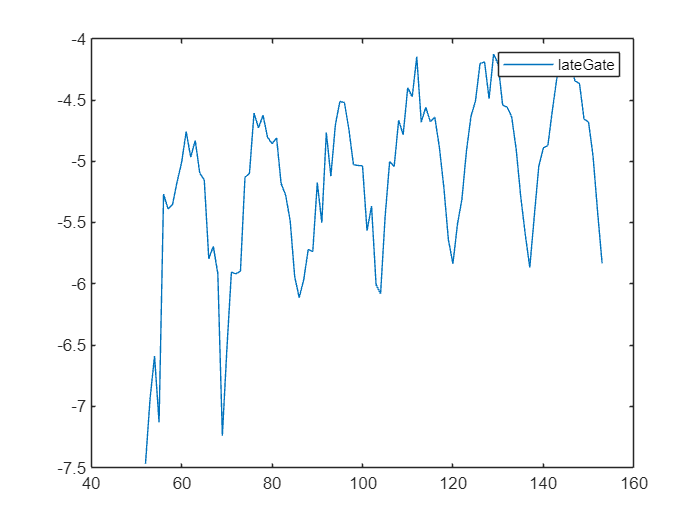

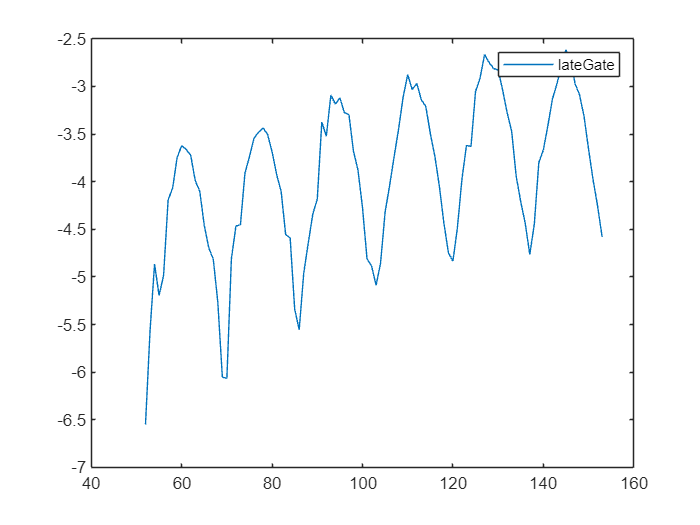

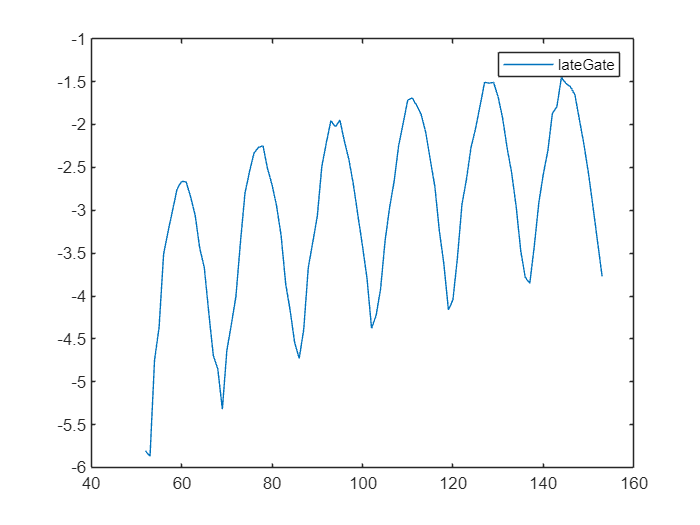

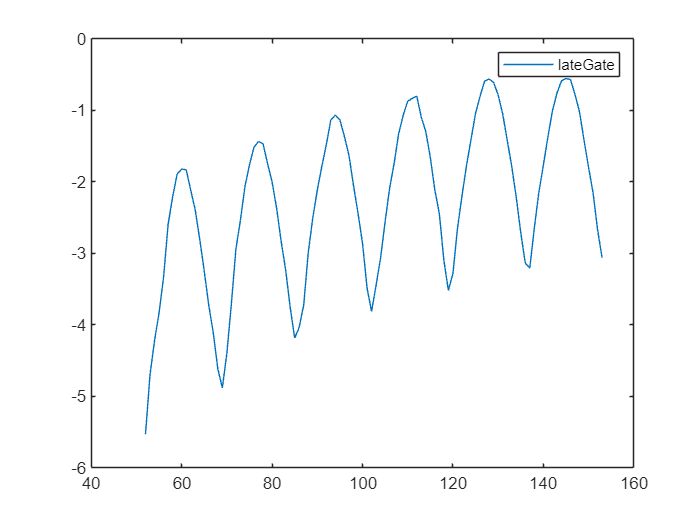

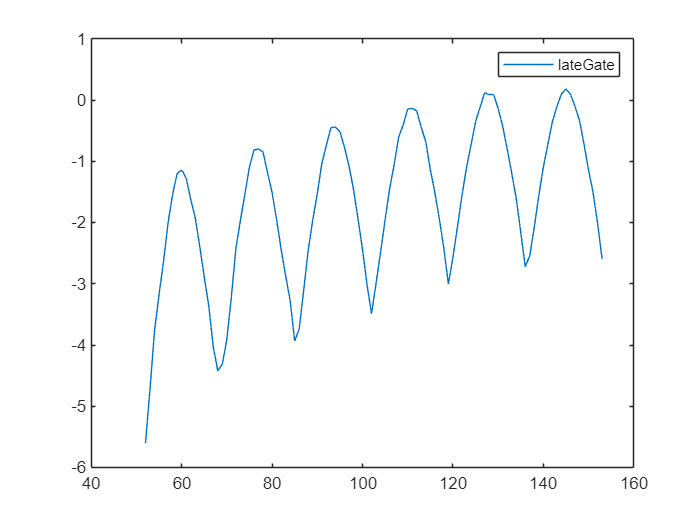

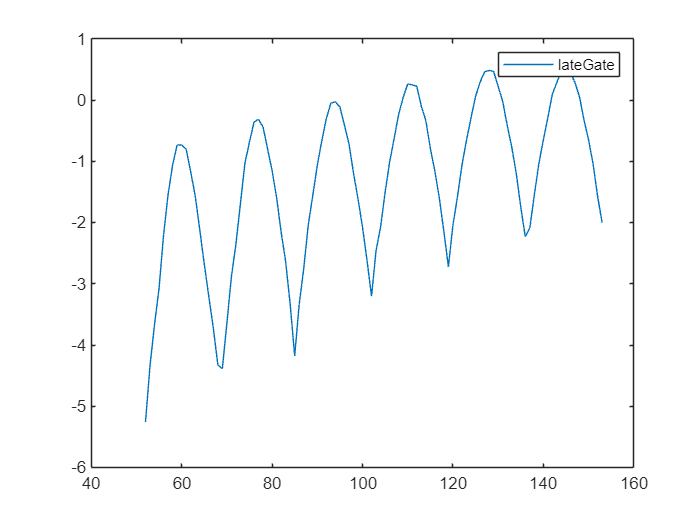

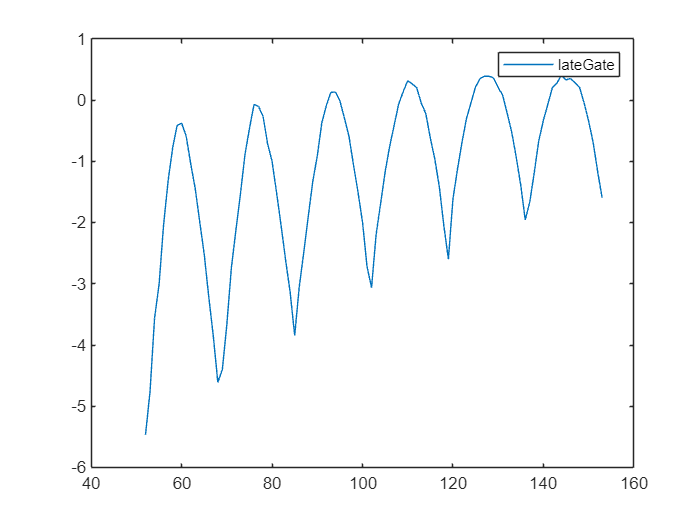

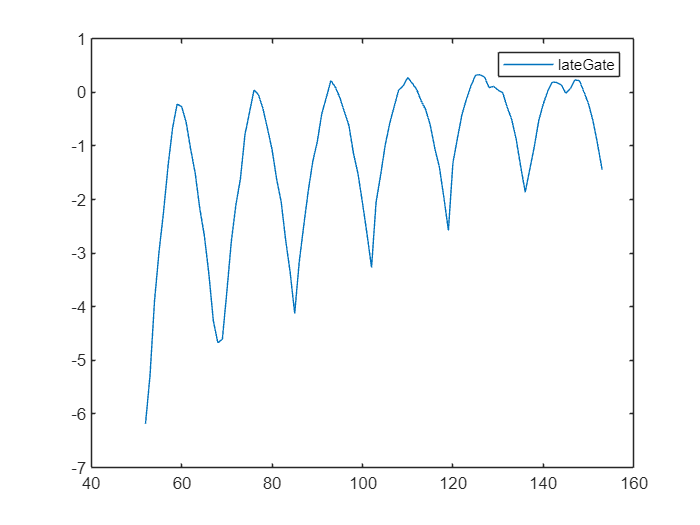

% input tpsf and Jacobians should be the normalized tpsf
% close all

%-----------data normalization------------
h = 6.626e-34; % Planck constant in Js
lambda = 800e-9; % wavelength in m
c = 299792453;
sp_eng = h.*c/(lambda); % single photon energy
% bandwidth = 1/exposure_time/2;
mpe = 3e-3; % w/mm^2
rep_rate = 300e6; % repetetion rate Hz 300M
single_pulse_energy = mpe./rep_rate; % J/mm^2
single_pulse_photon_count = single_pulse_energy./sp_eng;
exposure_time_tr = 1; % unit in second, the exposure time for the TCSPC
% BinFlag = (((1:length(cfg_csf.tstart:cfg_csf.tstep:cfg_csf.tend)-1)'-1).*cfg_csf.tstep+cfg_csf.tstep/2);
DCR = 100; % dark count rate 100/s
TCPSC_lim = 0.01*300e6;
% sensitive area is set to be 1mm^2
%-----------data normalization------------

tumour_pos_range = [20:5:54 54];

n = numel(tumour_pos_range);
metrics = {'m0','m1','m2','v','fullTPSF','earlyGate','lateGate'};

opt_FI = struct(); opt_D = struct();
for k = 1:numel(metrics)
    opt_FI.(metrics{k}) = zeros(n,1);
    opt_D.(metrics{k})  = zeros(n,1);
end

FI = struct(); D = struct();
for k = 1:numel(metrics)
    FI.(metrics{k}) = zeros(numel(SD_dist),1);
end

depth_index = 1;

% tumour_pos = 50
for tumour_pos = tumour_pos_range
    % % % % ----------update tumour mask -------------------
    tuct_pos1 = [tumour_pos 0];
    tuCt = [center_pos(1)-tuct_pos1(1) center_pos(2)+tuct_pos1(2)];
    tuR1 = 15;
    D2Cu = sqrt((grid_z-tuCt(1)).^2+(grid_y-tuCt(2)).^2);
    tumour_mask_it = zeros(2*brain_radius,2*brain_radius);
    for i = 1:size(tumour_mask_it,1)
        for j = 1:size(tumour_mask_it,2)
            if D2Cu(i,j)<=tuR1
                tumour_mask_it(i, j) = 1;
            end
        end
    end
    tumour_mask_it = rot90(tumour_mask_it);
    % figure;imagesc(tumour_mask_it);
    % imagesc(squeeze(log10(abs(sum(jacobians(:,:,:,1),3)))))
    % % % % ----------update tumour mask -------------------

    % data_load = load(sprintf("tpsfs_jacobians_AngRang_pi_3_tumpos%d.mat",tumour_pos));
    % data_load = load(sprintf("tpsfs_jacobians_tumpos%d.mat",tumour_pos));
    % data_load = load(sprintf("data3/tpsfs_jacobians_dense_AngRang_pi_3_tumpos%d.mat",tumour_pos));
    data_load = load(sprintf("data5/tpsfs_jacobians_dense_AngRang_pi_3_tumpos%d.mat",tumour_pos));

   
    %------------ normalize 1-----------make sure the highest count rate
    % % matches the TCSPC standard
    % data_load.tpsfs = data_load.tpsfs./max(sum(data_load.tpsfs,1)).*TCPSC_lim;
    % data_load.jacobians =  data_load.jacobians./max(sum(data_load.tpsfs,1)).*TCPSC_lim;
    %------------ normalize 1-----------make sure the highest count rate


    %--------------norm 2------------simple same norm
    tpsf_normalized_batch = data_load.tpsfs./cfg_csf.nphoton.*single_pulse_photon_count.*rep_rate*exposure_time_tr;
    Jacobians_norm_batch = data_load.jacobians./cfg_csf.nphoton.*single_pulse_photon_count.*rep_rate*exposure_time_tr;
    %--------------norm 2------------simple same norm

    % sd_ind = 111; % debug
    for sd_ind = 52:size(data_load.tpsfs,2) % starting from 52 to get rid of sampling noise

        % ----------- norm1-------------------
        % tpsf_sd =  data_load.tpsfs(:,sd_ind);
        % Jacobian_sd = squeeze(data_load.jacobians(:,:,:,sd_ind));
        % ----------- norm1-------------------

        % ------------ norm2-------------------
        tpsf_sd =  tpsf_normalized_batch(:,sd_ind);
        Jacobian_sd = squeeze(Jacobians_norm_batch(:,:,:,sd_ind));
        % ------------ norm2-------------------

        tpsf_normalized = tpsf_sd;
        Jacobians_norm = Jacobian_sd;
        % tpsf_normalized = tpsf_normalized+DCR*exposure_time_tr./length(tpsf_normalized); % plot(tpsf); hold on;
        J_Ni_mua = squeeze(sum(double(tumour_mask_it).*(Jacobians_norm),[1 2]));
        % figure;
        % plot(J_Ni_mua)

        %---------calculate the FI for moments-----------
        Em1 = sum(BinFlag.*tpsf_normalized,1)./sum(tpsf_normalized,1); % row vector
        Em2 = sum(BinFlag.^2.*tpsf_normalized,1)/sum(tpsf_normalized,1);
        Ev = Em2-Em1.^2;

        J_m0_Ni = ones(size(tpsf_normalized));
        J_m1_Ni = (BinFlag-Em1)./sum(tpsf_normalized,1); % col vector
        J_m2_Ni = (BinFlag.^2-Em2)./sum(tpsf_normalized,1);
        J_v_Ni = ((BinFlag-Em1).^2-Ev)./sum(tpsf_normalized,1);

        var_m1 = J_m1_Ni'*diag(tpsf_normalized)*J_m1_Ni;
        var_m2 = J_m2_Ni'*diag(tpsf_normalized)*J_m2_Ni;
        var_v = J_v_Ni'*diag(tpsf_normalized)*J_v_Ni;

        FI.(metrics{1})(sd_ind) = 1/sum(tpsf_normalized).*(J_m0_Ni'*J_Ni_mua).^2;
        FI.(metrics{2})(sd_ind) = 1/var_m1.*(J_m1_Ni'*J_Ni_mua).^2;
        FI.(metrics{3})(sd_ind) = 1/var_m2.*(J_m2_Ni'*J_Ni_mua).^2;
        FI.(metrics{4})(sd_ind) = 1/var_v.*(J_v_Ni'*J_Ni_mua).^2;

        %---------calculate the FI for full tpsf and time gates-----------
        one_over_tpsf = 1./tpsf_normalized';
        one_over_tpsf(isinf(one_over_tpsf)) = 0;
        % one_over_tpsf(find(one_over_tpsf>1)) = 0;
        FI.(metrics{5})(sd_ind) = one_over_tpsf*(J_Ni_mua).^2;
        FI.(metrics{6})(sd_ind) = 1/sum(tpsf_normalized(1:round(end/2))).*sum(J_Ni_mua(1:round(end/2))).^2;
        FI.(metrics{7})(sd_ind) =  1/sum(tpsf_normalized(round(end/2)+1:end)).*sum(J_Ni_mua(round(end/2)+1:end)).^2;
        %---------calculate the FI for full tpsf and time gates-----------
    end

    figure;
    % for ii = 1:numel(metrics)
    for ii = 7
        plot(log10(FI.(metrics{ii}))); hold on
    end
    legend(metrics{ii})

    % get rid of inf------------
    for ii = 1:numel(metrics)
        FI.(metrics{ii})(isinf(FI.(metrics{ii}))) = 0;
    end

    % selete optimal value and distance-------------
    for ii = 1:numel(metrics)
        [v,i] = max(FI.(metrics{ii}));
        opt_FI.(metrics{ii})(depth_index) = v;
        opt_D.(metrics{ii})(depth_index) = SD_dist(i);
    end

    depth_index = depth_index + 1;


end

## draw new picture  F4

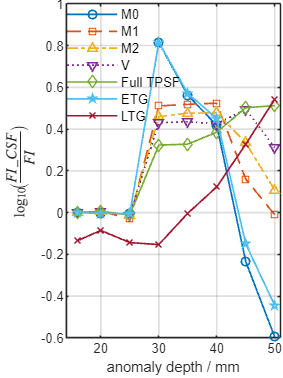

close all;

% -----------Desired sizes (cm)
figW = 6;   % figure width
figH = 8;    % figure height
axLeft = 5*0.282;  % left margin (from figure left edge)
axBottom = 3*0.282; % bottom margin
axW = figW-axLeft-0.05;    % axes width
axH = figH-axBottom-0.1;   % axes height


% -------- Create the figure at the given size
fig1 = figure;
ax1 = axes('Parent',fig1);

set(fig1, ...
    'Units',      'centimeters', ...
    'Position',   [2 2 figW figH], ...     % [left bottom width height]
    'PaperUnits', 'centimeters', ...
    'PaperPosition',[0 0 figW figH], ...
    'PaperSize',  [figW figH]);
set(ax1, ...
    'Units',      'centimeters', ...
    'Position',   [axLeft axBottom axW axH]);  % [left bottom width height] within fig

%-- Prepare data series and styles -----------------------------------------
x = brain_radius - tumour_pos_range;

lineSpecs = {'-','--','-.',':','-','-','-'};   % line styles
markers = {'o', 's', '^', 'v', 'd', 'p', 'x'};
% you can customize markers too, e.g. '-o','--s', etc.
% lineSpecs = {'-o','--s','-.^',':v','-d','-p','-x'};

labels = {'M0','M1','M2','V','Full TPSF','ETG','LTG'};

%-- Plot loop ---------------------------------------------------------------
hold on
for k = 1:numel(metrics)
    plot(ax1, x, log10(opt_FI_CSF.(metrics{k}))-log10(opt_FI.(metrics{k})), lineSpecs{k}, 'LineWidth', 1, 'Marker',markers{k},'MarkerSize',5);
end
hold off

%-- Beautify ----------------------------------------------------------------
% xlim(ax1,[13.7 53.7])
% ylim(ax1,[-6.66 -2.02])
xlabel('anomaly depth / mm');
ylabel('$\displaystyle \log_{10}\!\bigl(\frac{{FI\_CSF}}{{FI}}\bigr)$', ...
       'Interpreter','latex')
xlim(ax1, [14 51]);


grid on; box(ax1,'on');
ax = gca;
ax.LineWidth = 1;
ax.FontSize = 8;
ax.FontName = 'Arial';

legend(labels, "Position", [0.2191,0.66468,0.43612,0.3245], 'Box','off', ...
    'FontSize',8, 'FontName','arial');

print(fig1, 'F3_2_140825.png', '-dpng', '-r1200');



%---------generate sub fig with fixed axis
% 1) 

% % -----------Desired sizes (cm)
% figW_sub = 16.8/2;   % figure width
% figH_sub = 16.8*0.618/2;    % figure height
% axW  = 0.9*figW_sub;   % axes width
% axH  = figH_sub*0.9;    % axes height
% axLeft = (figW_sub-axW)./1.5;  % left margin (from figure left edge)
% axBottom = (figH_sub-axH)./1.5; % bottom margin
% 
% x_limits = [15.5 22];
% y_limits = [ -8.75 -7];
% fig11 = figure;
% set(fig11, ...
%     'Units','centimeters',  'Position',[2 2 figW_sub figH_sub], ...
%     'PaperUnits','centimeters','PaperPosition',[0 0 figW_sub figH_sub], ...
%     'PaperSize',[figW_sub figH_sub]);
% 
% % 2) 复制坐标区
% ax11 = copyobj(ax1, fig11);
% set(ax11, 'Units','centimeters', ...
%          'Position',[axLeft axBottom axW axH]);
% 
% % 3) 设置放大范围
% xlim(ax11, x_limits);
% ylim(ax11, y_limits);
% xlabel('')   % deletes the X‑label
% ylabel('')   % deletes the Y‑label
% title('')    % deletes the title (if needed)
% drawnow;  % draw zoom figure
% % 4) 导出
% % print(fig11,'F2S1_zoom.png','-dpng','-r1200');
% 
% 
% 
% %---------generate sub fig with fixed axis
% % 2 
% 
% % -----------Desired sizes (cm)
% figW_sub = 16.8/2;   % figure width
% figH_sub = 16.8*0.618/2;    % figure height
% axW  = 0.9*figW_sub;   % axes width
% axH  = figH_sub*0.9;    % axes height
% axLeft = (figW_sub-axW)./1.2;  % left margin (from figure left edge)
% axBottom = (figH_sub-axH)./1.5; % bottom margin
% 
% x_limits = [39 51];
% y_limits = [ -19.5 -15];
% fig12 = figure;
% set(fig12, ...
%     'Units','centimeters',  'Position',[2 2 figW_sub figH_sub], ...
%     'PaperUnits','centimeters','PaperPosition',[0 0 figW_sub figH_sub], ...
%     'PaperSize',[figW_sub figH_sub]);
% 
% % 2) 复制坐标区
% ax12 = copyobj(ax1, fig12);
% set(ax12, 'Units','centimeters', ...
%          'Position',[axLeft axBottom axW axH]);
% 
% % 3) 设置放大范围
% xlim(ax12, x_limits);
% ylim(ax12, y_limits);
% xlabel('')   % deletes the X‑label
% ylabel('')   % deletes the Y‑label
% title('')    % deletes the title (if needed)